clearvars;
files = dir('*sc.mat');
file = 2

file = 2


load(files(file).name)

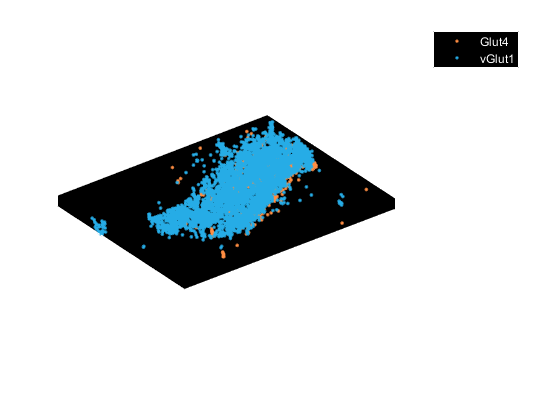

% Create a graph to visualize red and Orange data
ind_r = abs(cdata.red.zf) < 0.5;
ind_o = abs(cdata.orange.zf) < 0.5;
plot3(cdata.red.xf(ind_r),cdata.red.yf(ind_r),cdata.red.zf(ind_r),'.')
hold on
vector = xy_feature(cdata.orange.xf/cal.q,cdata.orange.yf/cal.q);
xf_o = cal.q*cal.o2rx.'*vector.';
yf_o = cal.q*cal.o2ry.'*vector.';
plot3(xf_o(ind_o), yf_o(ind_o),cdata.orange.zf(ind_o),'.')
hold off
axis equal
title('Non-corrected overlayed 3d localization data')
legend('Glut4','vGlut1')

correction = cdata.orange.zf - cdata.orange.zf_raw;

% plot3(cdata.red.xf(ind_r),cdata.red.yf(ind_r),cdata.red.zf_smoothed(ind_r),'.')
% hold on

l=2;

plot3(xf_o(ind_o), yf_o(ind_o),cdata.orange.zf(ind_o) - correction(ind_o)*l,'.')
% plot(xf_o(ind_o), yf_o(ind_o),'.')
hold off
axis equal
% title('Fixed BEAS w/ tubulin ')
legend('PA-JF','Glitter Bomb','Location',"northwest")

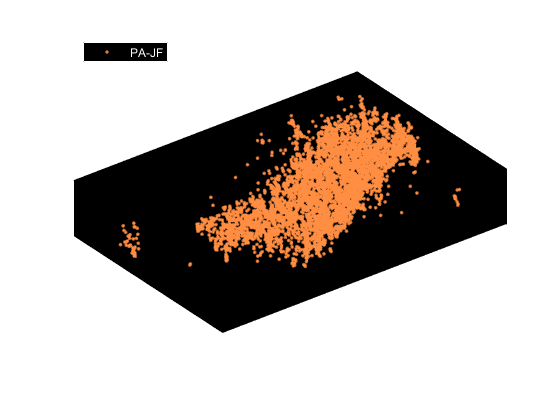

% legend('Glitter Bomb','Location',"northwest")
xlabel('Microns')
ylabel('Microns')
% 
% 
%     clear M
%     view(0,30)
%     M = getframe(gcf)
%     for i = 1:359
%         view(i,30);
%         M(numel(M)+1) = getframe(gcf);
%     end
%     
% 
% movie2gif(M,'glut4_surface.gif','DelayTime',0.03,'LoopCount',Inf)
whitebg([0 0 0])

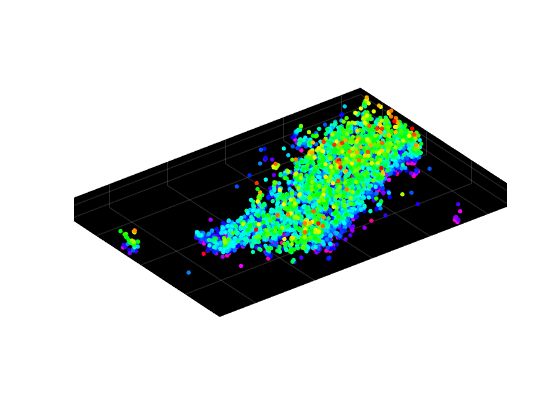

% % Cluster Analysis
% cdata.red.clusts = DB_scan([cdata.red.xf,cdata.red.yf], 0.1,10);
% for i = 1:max(cdata.red.clusts)
%     ind = cdata.red.clusts == i;
%     plot3(cdata.red.xf(ind) - mean(cdata.red.xf(ind)), cdata.red.yf(ind) - mean(cdata.red.yf(ind)) ,cdata.red.yf(ind)*0+i,'.');
%     hold on
% end
% hold off
s = scatter3(cdata.orange.xf(ind_o),cdata.orange.yf(ind_o),-cdata.orange.zf_smoothed(ind_o),7,cdata.orange.zf_smoothed(ind_o));
s.MarkerFaceColor = s.MarkerEdgeColor;
colormap('hsv')
axis equal

% histogram(cdata.red.clusts(ind_r))

% ind_r2 = ind_r & cdata.red.clusts == 0;
% s = scatter3(cdata.red.xf,cdata.red.yf,cdata.red.zf_raw,5,cdata.red.clusts);
% s.MarkerFaceColor = s.MarkerEdgeColor;
% axis equal
% legend('Added','Subtracted')
% plot(cdata.red.framenumber,cdata.red.zf_raw-cdata.red.zf,'.')